clc;
clear all;
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[-0.142;-4.31;7.83];
u31=[0.221;0.975;0];
r2=[0.142;4.31;-7.94];
u32=[-0.221;-0.975;0];
r3=[15.31;4.31;-2.24];
u33=[0.221;0.975;0];
r4=[15.03;-4.31;-18.01];
u34=[-0.221;-0.975;0];
r5=[15.59;12.93;-18.01];
u35=[-0.221;-0.975;0];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];

% center and direction of spheroids
hold on
axis([5 15 5 15]);
for R3=5:0.2:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3]; 
end

ans =    14.8600    5.0000    1.0002


ans =    13.6300    5.2000    1.0003


ans =    12.7600    5.4000    1.0000


ans =    12.1000    5.6000    1.0004


ans =    11.5900    5.8000    1.0003


ans =    11.1800    6.0000    1.0004


ans =    10.8400    6.2000    1.0009


ans =    10.5600    6.4000    1.0010


ans =    10.3300    6.6000    1.0003


ans =    10.1200    6.8000    1.0012


ans =     9.9500    7.0000    1.0005


ans =     9.8000    7.2000    1.0001


ans =     9.6600    7.4000    1.0008


ans =     9.5400    7.6000    1.0008


ans =     9.4300    7.8000    1.0013


ans =     9.3400    8.0000    1.0005


ans =     9.2500    8.2000    1.0011


ans =     9.1700    8.4000    1.0014


ans =     9.1000    8.6000    1.0013


ans =     9.0400    8.8000    1.0005


ans =     8.9800    9.0000    1.0006


ans =     8.9200    9.2000    1.0016


ans =     8.8700    9.4000    1.0016


ans =     8.8300    9.6000    1.0005


ans =     8.7900    9.8000    1.0000


ans =     8.7500   10.0000    1.0001


ans =     8.7100   10.2000    1.0007


ans =     8.6700   10.4000    1.0018


ans =     8.6400   10.6000    1.0014


ans =     8.6100   10.8000    1.0014


ans =     8.5800   11.0000    1.0018


ans =     8.5600   11.2000    1.0006


ans =     8.5300   11.4000    1.0016


ans =     8.5100   11.6000    1.0010


ans =     8.4900   11.8000    1.0006


ans =     8.4700   12.0000    1.0005


ans =     8.4500   12.2000    1.0006


ans =     8.4300   12.4000    1.0009


ans =     8.4100   12.6000    1.0014


ans =     8.4000   12.8000    1.0000


ans =     8.3800   13.0000    1.0010


ans =     8.3600   13.2000    1.0021


ans =     8.3500   13.4000    1.0012


ans =     8.3400   13.6000    1.0004


ans =     8.3200   13.8000    1.0020


ans =     8.3100   14.0000    1.0015


ans =     8.3000   14.2000    1.0011


ans =     8.2900   14.4000    1.0009


ans =     8.2800   14.6000    1.0007


ans =     8.2700   14.8000    1.0007


ans = 1×3
    8.2600   15.0000    1.0007


plot(x1,y1,'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'DisplayName','1-2')


for R3=5:0.2:15 %离心率
    R1=8;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r3,R1,R3,u32,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3]; 
end

ans = 1×3
    8.4100    5.0000    1.0007


ans = 1×3
    8.3700    5.2000    1.0007


ans = 1×3
    8.3300    5.4000    1.0018


ans = 1×3
    8.3000    5.6000    1.0016


ans = 1×3
    8.2700    5.8000    1.0022


ans = 1×3
    8.2500    6.0000    1.0012


ans = 1×3
    8.2300    6.2000    1.0007


ans = 1×3
    8.2100    6.4000    1.0007


ans = 1×3
    8.1900    6.6000    1.0012


ans = 1×3
    8.1700    6.8000    1.0020


ans = 1×3
    8.1600    7.0000    1.0009


ans = 1×3
    8.1500    7.2000    1.0001


ans = 1×3
    8.1300    7.4000    1.0019


ans = 1×3
    8.1200    7.6000    1.0016


ans = 1×3
    8.1100    7.8000    1.0014


ans = 1×3
    8.1000    8.0000    1.0015


ans = 1×3
    8.0900    8.2000    1.0018


ans = 1×3
    8.0800    8.4000    1.0022


ans = 1×3
    8.0800    8.6000    1.0004


ans = 1×3
    8.0700    8.8000    1.0010


ans = 1×3
    8.0600    9.0000    1.0018


ans = 1×3
    8.0600    9.2000    1.0004


ans = 1×3
    8.0500    9.4000    1.0014


ans = 1×3
    8.0500    9.6000    1.0000


ans = 1×3
    8.0400    9.8000    1.0012


ans = 1×3
    8.0400   10.0000    1.0001


ans = 1×3
    8.0300   10.2000    1.0014


ans = 1×3
    8.0300   10.4000    1.0004


ans = 1×3
    8.0200   10.6000    1.0018


ans = 1×3
    8.0200   10.8000    1.0009


ans = 1×3
    8.0200   11.0000    1.0000


ans = 1×3
    8.0100   11.2000    1.0017


ans = 1×3
    8.0100   11.4000    1.0009


ans = 1×3
    8.0100   11.6000    1.0001


ans = 1×3
    8.0000   11.8000    1.0019


ans = 1×3
    8.0000   12.0000    1.0012


ans = 1×3
    8.0000   12.2000    1.0006


ans = 1×3
    7.9900   12.4000    1.0024


ans = 1×3
    7.9900   12.6000    1.0019


ans = 1×3
    7.9900   12.8000    1.0013


ans = 1×3
    7.9900   13.0000    1.0008


ans = 1×3
    7.9900   13.2000    1.0003


ans = 1×3
    7.9800   13.4000    1.0023


ans = 1×3
    7.9800   13.6000    1.0018


ans = 1×3
    7.9800   13.8000    1.0014


ans = 1×3
    7.9800   14.0000    1.0010


ans = 1×3
    7.9800   14.2000    1.0006


ans = 1×3
    7.9800   14.4000    1.0002


ans = 1×3
    7.9700   14.6000    1.0023


ans = 1×3
    7.9700   14.8000    1.0019


ans = 1×3
    7.9700   15.0000    1.0016



plot(x2,y2,'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'DisplayName','2-3')


for R3=5:0.2:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r4,R1,R3,u32,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans = 1×3
   11.2000    5.0000    1.0011


ans = 1×3
   11.0600    5.2000    1.0003


ans = 1×3
   10.9300    5.4000    1.0009


ans = 1×3
   10.8200    5.6000    1.0011


ans = 1×3
   10.7300    5.8000    1.0003


ans = 1×3
   10.6400    6.0000    1.0013


ans = 1×3
   10.5700    6.2000    1.0007


ans = 1×3
   10.5000    6.4000    1.0013


ans = 1×3
   10.4400    6.6000    1.0015


ans = 1×3
   10.3900    6.8000    1.0010


ans = 1×3
   10.3400    7.0000    1.0014


ans = 1×3
   10.3000    7.2000    1.0009


ans = 1×3
   10.2600    7.4000    1.0010


ans = 1×3
   10.2200    7.6000    1.0017


ans = 1×3
   10.1900    7.8000    1.0012


ans = 1×3
   10.1600    8.0000    1.0012


ans = 1×3
   10.1300    8.2000    1.0016


ans = 1×3
   10.1100    8.4000    1.0006


ans = 1×3
   10.0800    8.6000    1.0018


ans = 1×3
   10.0600    8.8000    1.0014


ans = 1×3
   10.0400    9.0000    1.0014


ans = 1×3
   10.0200    9.2000    1.0016


ans = 1×3
   10.0100    9.4000    1.0002


ans = 1×3
    9.9900    9.6000    1.0008


ans = 1×3
    9.9700    9.8000    1.0017


ans = 1×3
    9.9600   10.0000    1.0009


ans = 1×3
    9.9500   10.2000    1.0002


ans = 1×3
    9.9300   10.4000    1.0016


ans = 1×3
    9.9200   10.6000    1.0012


ans = 1×3
    9.9100   10.8000    1.0010


ans = 1×3
    9.9000   11.0000    1.0009


ans = 1×3
    9.8900   11.2000    1.0009


ans = 1×3
    9.8800   11.4000    1.0010


ans = 1×3
    9.8700   11.6000    1.0012


ans = 1×3
    9.8600   11.8000    1.0015


ans = 1×3
    9.8500   12.0000    1.0019


ans = 1×3
    9.8500   12.2000    1.0004


ans = 1×3
    9.8400   12.4000    1.0010


ans = 1×3
    9.8300   12.6000    1.0016


ans = 1×3
    9.8300   12.8000    1.0003


ans = 1×3
    9.8200   13.0000    1.0010


ans = 1×3
    9.8100   13.2000    1.0018


ans = 1×3
    9.8100   13.4000    1.0007


ans = 1×3
    9.8000   13.6000    1.0016


ans = 1×3
    9.8000   13.8000    1.0006


ans = 1×3
    9.7900   14.0000    1.0016


ans = 1×3
    9.7900   14.2000    1.0007


ans = 1×3
    9.7800   14.4000    1.0018


ans = 1×3
    9.7800   14.6000    1.0009


ans = 1×3
    9.7800   14.8000    1.0001


ans = 1×3
    9.7700   15.0000    1.0013


plot(x3,y3,'color',[63, 125, 162]/256, ...
    'LineWidth',1.5,'DisplayName','2-4')

for R3=7:0.2:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r5,R1,R3,u32,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r5,R1,R3,u32,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r5,R1,R3,u32,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];  
end

ans = 1×3
   15.4400    7.0000    1.0001


ans = 1×3
   14.4900    7.2000    1.0002


ans = 1×3
   13.7600    7.4000    1.0001


ans = 1×3
   13.1700    7.6000    1.0002


ans = 1×3
   12.6900    7.8000    1.0002


ans = 1×3
   12.2900    8.0000    1.0001


ans = 1×3
   11.9500    8.2000    1.0001


ans = 1×3
   11.6500    8.4000    1.0008


ans = 1×3
   11.4000    8.6000    1.0005


ans = 1×3
   11.1800    8.8000    1.0003


ans = 1×3
   10.9800    9.0000    1.0007


ans = 1×3
   10.8100    9.2000    1.0002


ans = 1×3
   10.6500    9.4000    1.0006


ans = 1×3
   10.5100    9.6000    1.0006


ans = 1×3
   10.3800    9.8000    1.0009


ans = 1×3
   10.2700   10.0000    1.0002


ans = 1×3
   10.1600   10.2000    1.0009


ans = 1×3
   10.0700   10.4000    1.0000


ans = 1×3
    9.9800   10.6000    1.0002


ans = 1×3
    9.8900   10.8000    1.0014


ans = 1×3
    9.8200   11.0000    1.0007


ans = 1×3
    9.7500   11.2000    1.0007


ans = 1×3
    9.6900   11.4000    1.0000


ans = 1×3
    9.6200   11.6000    1.0015


ans = 1×3
    9.5700   11.8000    1.0005


ans = 1×3
    9.5200   12.0000    1.0002


ans = 1×3
    9.4700   12.2000    1.0003


ans = 1×3
    9.4200   12.4000    1.0009


ans = 1×3
    9.3800   12.6000    1.0004


ans = 1×3
    9.3400   12.8000    1.0003


ans = 1×3
    9.3000   13.0000    1.0005


ans = 1×3
    9.2600   13.2000    1.0012


ans = 1×3
    9.2300   13.4000    1.0005


ans = 1×3
    9.2000   13.6000    1.0001


ans = 1×3
    9.1600   13.8000    1.0017


ans = 1×3
    9.1400   14.0000    1.0001


ans = 1×3
    9.1100   14.2000    1.0005


ans = 1×3
    9.0800   14.4000    1.0012


ans = 1×3
    9.0600   14.6000    1.0003


ans = 1×3
    9.0300   14.8000    1.0015


ans = 1×3
    9.0100   15.0000    1.0010


plot(x4,y4,'color',[239, 193, 48]/256, ...
    'LineWidth',1.5,'DisplayName','2-5')

for R1=5:0.2:15 %离心率
    R3=8.5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r4,r5,R1,R3,u34,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];  
end

ans = 1×3
    5.0000    8.9600    1.0006


ans = 1×3
    5.2000    8.9200    1.0005


ans = 1×3
    5.4000    8.8800    1.0015


ans = 1×3
    5.6000    8.8500    1.0012


ans = 1×3
    5.8000    8.8200    1.0016


ans = 1×3
    6.0000    8.8000    1.0006


ans = 1×3
    6.2000    8.7800    1.0000


ans = 1×3
    6.4000    8.7500    1.0021


ans = 1×3
    6.6000    8.7400    1.0003


ans = 1×3
    6.8000    8.7200    1.0011


ans = 1×3
    7.0000    8.7000    1.0021


ans = 1×3
    7.2000    8.6900    1.0013


ans = 1×3
    7.4000    8.6800    1.0007


ans = 1×3
    7.6000    8.6700    1.0004


ans = 1×3
    7.8000    8.6600    1.0002


ans = 1×3
    8.0000    8.6500    1.0002


ans = 1×3
    8.2000    8.6400    1.0004


ans = 1×3
    8.4000    8.6300    1.0008


ans = 1×3
    8.6000    8.6200    1.0012


ans = 1×3
    8.8000    8.6100    1.0018


ans = 1×3
    9.0000    8.6100    1.0003


ans = 1×3
    9.2000    8.6000    1.0011


ans = 1×3
    9.4000    8.5900    1.0020


ans = 1×3
    9.6000    8.5900    1.0007


ans = 1×3
    9.8000    8.5800    1.0018


ans = 1×3
   10.0000    8.5800    1.0007


ans = 1×3
   10.2000    8.5700    1.0019


ans = 1×3
   10.4000    8.5700    1.0009


ans = 1×3
   10.6000    8.5600    1.0023


ans = 1×3
   10.8000    8.5600    1.0014


ans = 1×3
   11.0000    8.5600    1.0005


ans = 1×3
   11.2000    8.5500    1.0020


ans = 1×3
   11.4000    8.5500    1.0012


ans = 1×3
   11.6000    8.5500    1.0005


ans = 1×3
   11.8000    8.5400    1.0021


ans = 1×3
   12.0000    8.5400    1.0015


ans = 1×3
   12.2000    8.5400    1.0009


ans = 1×3
   12.4000    8.5400    1.0003


ans = 1×3
   12.6000    8.5300    1.0020


ans = 1×3
   12.8000    8.5300    1.0015


ans = 1×3
   13.0000    8.5300    1.0009


ans = 1×3
   13.2000    8.5300    1.0004


ans = 1×3
   13.4000    8.5200    1.0023


ans = 1×3
   13.6000    8.5200    1.0018


ans = 1×3
   13.8000    8.5200    1.0014


ans = 1×3
   14.0000    8.5200    1.0010


ans = 1×3
   14.2000    8.5200    1.0006


ans = 1×3
   14.4000    8.5200    1.0002


ans = 1×3
   14.6000    8.5100    1.0021


ans = 1×3
   14.8000    8.5100    1.0018


ans = 1×3
   15.0000    8.5100    1.0014


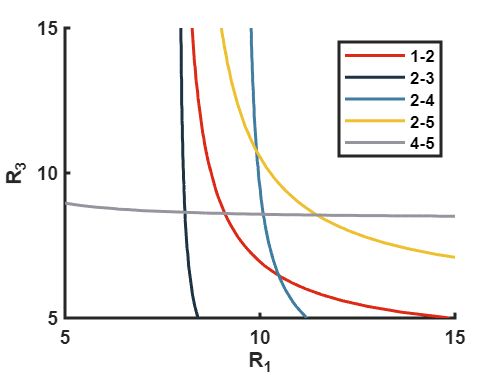

plot(x5,y5,'color',[151, 150, 159]/256, ...
    'LineWidth',1.5,'DisplayName','4-5')


hold off


set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast');

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end
